# Audio effects in Matlab

Vladislav Serafimov 509761

## Flanger

clc;
clear;
[x, fs] = audioread("sine.mp3");
delay = 15; 
range = 12;
sf = 0.3125;
max = length(x) - (delay + range);
y = zeros(1, max);
for i = 1:max
    y(i) = x(i) + x(i + delay + round(range*sin((2*pi*i*sf)/fs)));
end
audiowrite('sine_flan.wav', y, fs);

## Amplitude modulator

clc;
clear;
[x, fs] = audioread("sine.mp3");
f_mod = 1;
alpha = .5; %modulation depth
max = length(x);
t = linspace(0, max/fs, max);
sine = sin(2*pi*f_mod*t);
y = zeros(1, max);
for i = 1:max
    y(i) = (1 + alpha*sine(i)*f_mod*x(i));
end
audiowrite('sine_amp_mod.wav', y, fs);

## Both at the same time

clc;
clear;
[x, fs] = audioread("sine_flan.wav");
f_mod = 1;
alpha = .5; %modulation depth
max = length(x);    
t = linspace(0, max/fs, max);
sine = sin(2*pi*f_mod*t);
y = zeros(1, max);
for i = 1:max
    y(i) = (1 + alpha*sine(i)*f_mod*x(i));
end
audiowrite('sine_both.wav', y, fs);

## Plots

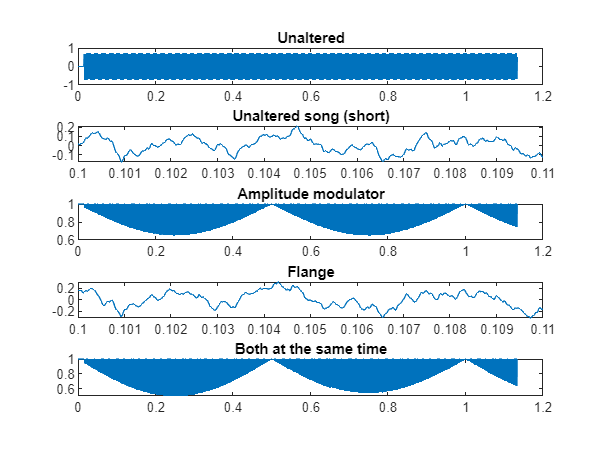

n = 50000; %samples to plot
[x1, fs1] = audioread("sine.mp3");
[x2, fs2] = audioread("sine_amp_mod.wav");
[x3, fs3] = audioread("cbat_flan.wav");
[x5, fs5] = audioread("cbat.mp3");
[x4, fs4] = audioread("sine_both.wav");
t = (0:length(x1)-1)/fs1;
t_use = t(1:n);

subplot(5,1,1)
plot(t_use, x1(1:n))
title("Unaltered")

subplot(5,1,2)
plot(t_use, x5(1:n))
xlim([0.1 0.11])
title("Unaltered song (short)")

subplot(5,1,3)
plot(t_use, x2(1:n))
title("Amplitude modulator")

subplot(5,1,4)
plot(t_use, x3(1:n))
xlim([0.1 0.11])
title("Flange")

subplot(5,1,5)
plot(t_use, x4(1:n))
title("Both at the same time")


figure